## Crear histograma

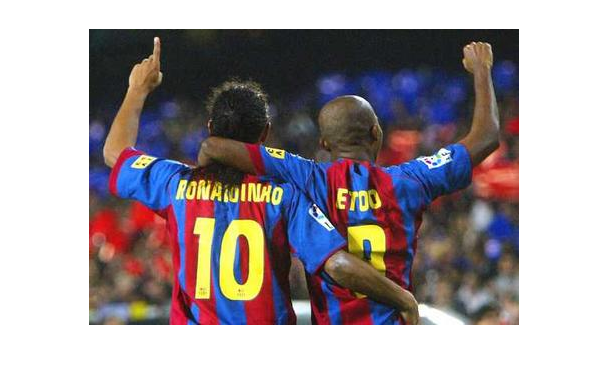

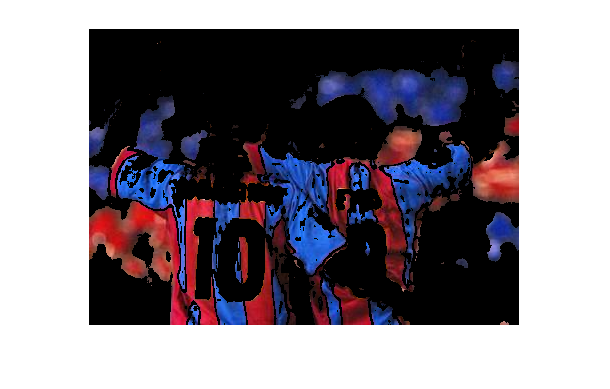

im = imread("barcelona\39.jpg");
filter = crearHistograma(im);

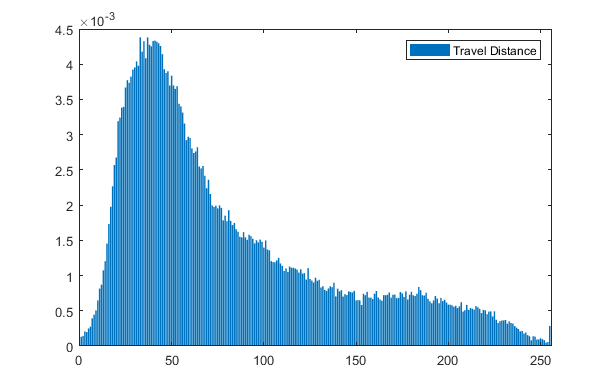

r = filter(:,:,1);
g = filter(:,:,2);
b = filter(:,:,3);
rh = imhist(r);
gh = imhist(g);
bh = imhist(b);
rh = rh.';
gh = gh.';
bh = bh.';
rh = rh/sum(rh);
gh = gh/sum(gh);
bh = bh/sum(bh);

h = imhist(filter);
h = h/sum(h);
h = h(2:256);
   bar(h, 'DisplayName', 'Travel Distance'); 
  legend('show');



%rht = imhist(filter(:,:,1));
%subrht = rht(2:256);
%plot(subrht);
%ght = imhist(filter(:,:,2));
%subght = ght(2:256);
%plot(subght);
%bht = imhist(filter(:,:,3));
%subbht = bht(2:256);
%plot(subbht);
imshow(filter);

imshow(im);

## Comparacion

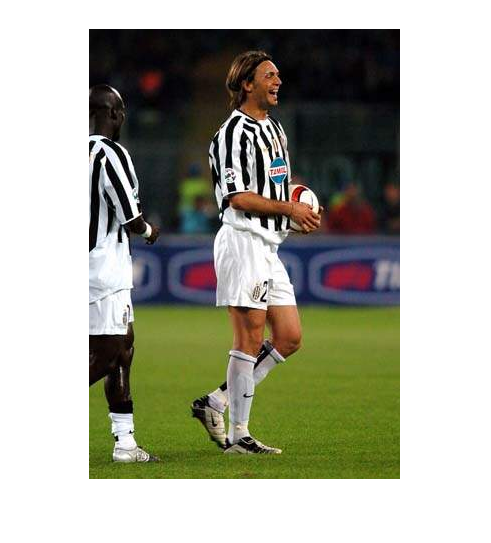

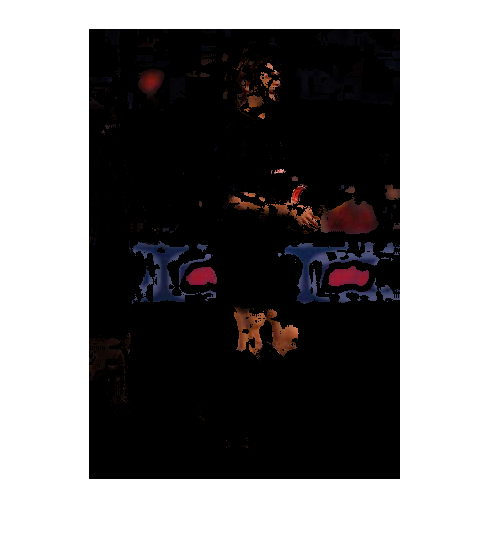

comp = imread('juventus/02.jpg');

compfilter = crearHistograma(comp);

r2 = compfilter(:,:,1);
g2 = compfilter(:,:,2);
b2 = compfilter(:,:,3);
rh2 = imhist(r2);
gh2 = imhist(g2);
bh2 = imhist(b2);
rh2 = rh2.';
gh2 = gh2.';
bh2 = bh2.';
rh2 = rh2/sum(rh2);
gh2 = gh2/sum(gh2);
bh2 = bh2/sum(bh2);

kr = chiDistance(rh,rh2);
kr

kr = NaN

kg = chiDistance(gh,gh2);
kg

kg = NaN

kb = chiDistance(bh,bh2);
kb

kb = 0.2606


%h2 = imhist(compfilter);
%h2 = h2/sum(h2);
%h2 = h2(2:256);
   %bar(h2, 'DisplayName', 'Travel Distance'); 
  %legend('show');



%rh = imhist(compfilter(:,:,1));
%subrh = rh(2:256);
%plot(subrh);
%gh = imhist(compfilter(:,:,2));
%subgh = gh(2:256);
%plot(subgh);
%bh = imhist(compfilter(:,:,3));
%subbh = bh(2:256);
%plot(subbh);
imshow(compfilter);

%k = pdist2(rh,rht,"euclidean");
%k

function [imFilter] = crearHistograma(ip)
imshow(ip);
f = size(ip,1);
c = size(ip,2);

r=ip(:,:,1);
g=ip(:,:,2);
b=ip(:,:,3);
I=double(r)+double(g)+double(b);
rn=double(r)./I;
gn=double(g)./I;
bn=double(b)./I;
rgbNorm=cat(3,rn,gn,bn);
figure,imshow(rgbNorm),title('Imagen normalizada');
imFilter = uint8(zeros(f,c));
for i=1:f
    for j=1:c
        if rgbNorm(i,j,1) > 0.4
            if rgbNorm(i,j,2) < 0.3
                if rgbNorm(i,j,3) < 0.3
                    imFilter(i,j,1:3) = ip(i,j,1:3);
                end
            end
        end
        if rgbNorm(i,j,3) > 0.4
            if rgbNorm(i,j,2) < 0.3
                if rgbNorm(i,j,1) < 0.3
                    imFilter(i,j,1:3) = ip(i,j,1:3);
                end
            end
        end
    end
end
imshow(imFilter)
end


function [d] = chiDistance(xi,yi)
d = double(0);
for i=1:length(xi)
    up = xi(i) - yi(i);
    down = xi(i) + yi(i);
    d = d + (up^2 / down);
end
end